# BUCK CONVERTER CURRENT MODE CONTROL

clc
close all
clear all

## PLANT PARAMETERS

% Voltage Requirement [V]
Vin = 12;
Vo = 3.3;

%Duty Ratio
Duty_desired = 3.3/12

Duty_desired = 0.2750


%Switching Frequency [Hz]
fs = 500e3;

%Load Requirement [A]
Imax = 20;
Imin = 2;
Inom = 10;

%Load Calculation [Ohm]
Rmin = Vo/Imax

Rmin = 0.1650

Rmax = Vo/Imin

Rmax = 1.6500

Rnom = Vo/Inom

Rnom = 0.3300


%Inductor [H]
L = 2e-6;
%Winding Resistor [Ohm]
rL = 20e-3;

%Capacitor [F]
C = 220e-6;
%ESR [Ohm]
rC = 10e-3;

### Plant Transfer Function

% Plant Transfer function
Gp = tf([Rmin*rC*C,Rmin],[Rmin*C,1]);

%Plant Gain, Zero and Pole Frequency [Hz]
[z_plant,p_plant,k_plant] = tf2zpk([Rmin*rC*C,Rmin],[Rmin*C,1]);
k_plant

k_plant = 0.0100

fz_plant = -z_plant/2/pi

fz_plant = 7.2343e+04

fp_plant = -p_plant/2/pi

fp_plant = 4.3844e+03

% pole_plant = pole(Gp)
% zero_plant = zero(Gp)

### BODE

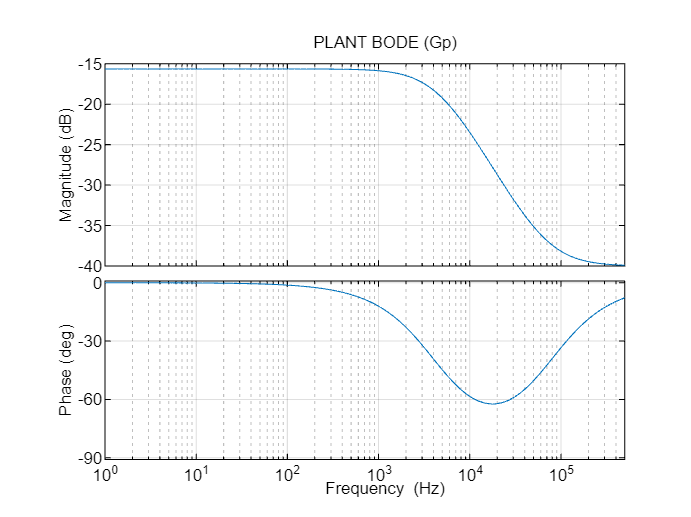

options = bodeoptions;
options.FreqUnits = 'Hz';
bode(Gp,{2*pi,500e3*2*pi},options)
grid on
title("PLANT BODE (Gp)")

### COMBINED TRANSFER FUNCTION AND BODE

% Plant Transfer function for different Loads
Gp_100 = tf([Rmin*rC*C,Rmin],[Rmin*C,1])

Gp_100 =
 
  3.63e-07 s + 0.165
  ------------------
    3.63e-05 s + 1
 
Continuous-time transfer function.
Model Properties


Gp_10 = tf([Rmax*rC*C,Rmax],[Rmax*C,1])

Gp_10 =
 
  3.63e-06 s + 1.65
  -----------------
   0.000363 s + 1
 
Continuous-time transfer function.
Model Properties


Gp_75 = tf([Rnom*rC*C,Rnom],[Rnom*C,1])

Gp_75 =
 
  7.26e-07 s + 0.33
  -----------------
   7.26e-05 s + 1
 
Continuous-time transfer function.
Model Properties


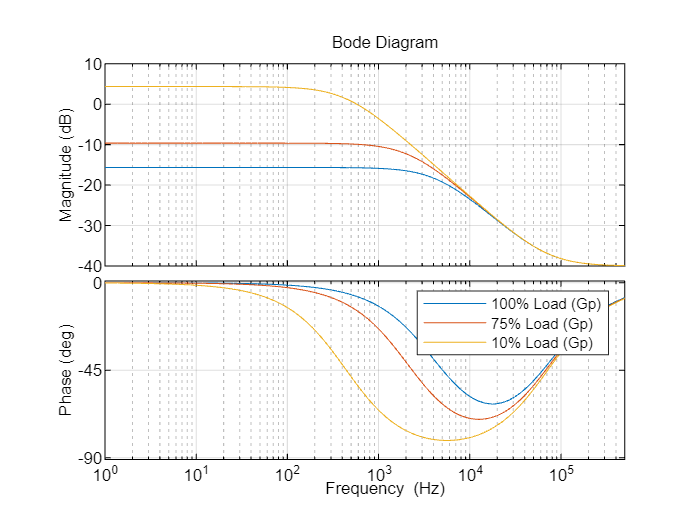


%Bode
options = bodeoptions;
options.FreqUnits = 'Hz';
bode(Gp_100,Gp_75, Gp_10, {2*pi,500e3*2*pi},options)
grid on
legend("100% Load (Gp)","75% Load (Gp)","10% Load (Gp)")

## COMPENSATOR PARAMETERS

%Desired Crossover Frequency [Hz]
fc = 25e3;

%Desired Phase Margin [deg]
PM = 45;

%Plant Gain at Crossover Frequency
Gain_fc_dB = mag2db(abs(evalfr(Gp,j*2*pi*fc)))

Gain_fc_dB = -30.4125

Gain_fc = abs(evalfr(Gp,j*2*pi*fc))

Gain_fc = 0.0302

% Gain_fc1 = abs(Rmin*(1+j*2*pi*fc*rC*C)/(1+j*2*pi*fc*Rmin*C))

%Plant Phase at Crossover Frequency [deg]
Phase_fc = rad2deg(angle(evalfr(Gp,j*2*pi*fc)))

Phase_fc = -60.9889

% Phase_fc1 = angle(Rmin*(1+j*2*pi*fc*rC*C)/(1+j*2*pi*fc*Rmin*C))*180/pi

%Phase needed from Compensator
phi_boost = -90 + PM - Phase_fc

phi_boost = 15.9889


%Gain needed from Compensator
gain_need = 1/Gain_fc

gain_need = 33.1607

gain_need_dB = -Gain_fc_dB

gain_need_dB = 30.4125


%Compensator Pole Zero Separation
K_boost = tand(45 + phi_boost/2)

K_boost = 1.3268

% K_boost = 5

%Compensator Zero [rad/sec]
wz_comp = 2*pi*fc/K_boost;
fz_comp = wz_comp/2/pi

fz_comp = 1.8843e+04


%Compensator Pole [rad/sec]
wp_comp = 2*pi*fc*K_boost;
fp_comp = wp_comp/2/pi

fp_comp = 3.3169e+04


%Compensator Gain
k_comp = wz_comp / Gain_fc

k_comp = 3.9260e+06

### Controller Transfer Function

Gc = tf([k_comp/wz_comp,k_comp],[1/wp_comp,1,0]);

### BODE

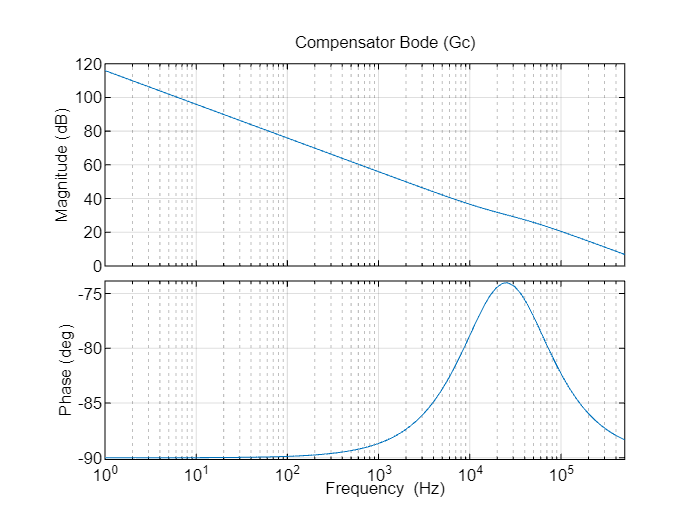

options = bodeoptions;
options.FreqUnits = 'Hz';
bode(Gc,{2*pi,500e3*2*pi},options)
grid on
title("Compensator Bode (Gc)")

## SYSTEM OPEN LOOP

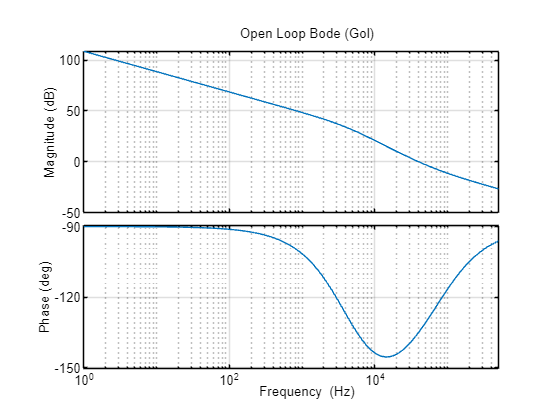

Gol = Gp*Gc;

%Bode
options = bodeoptions;
options.FreqUnits = 'Hz';
bode(Gol,{2*pi,500e3*2*pi},options)
grid on
title("Open Loop Bode (Gol)")


[Gm_ol,Pm_ol,Wcg_ol,Wcp_ol] = margin(Gol);
fc_OL = Wcp_ol/2/pi

fc_OL = 9.9997e+03

PM_OL = Pm_ol

PM_OL = 45.0005

## SYSTEM CLOSED LOOP

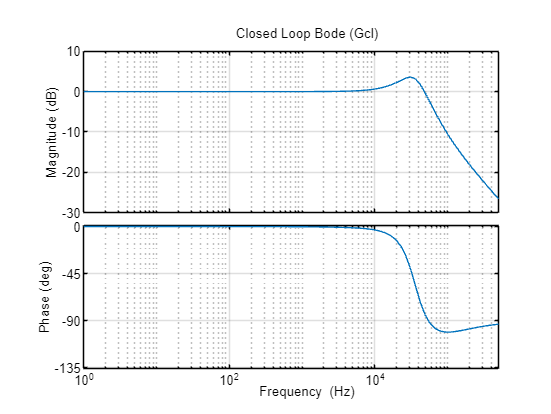

Gcl = feedback(Gp*Gc,1);

%Bode
options = bodeoptions;
options.FreqUnits = 'Hz';
bode(Gcl,{2*pi,500e3*2*pi},options)
grid on
title("Closed Loop Bode (Gcl)")